# Getting Started with teh SDMX Toolbox

**Simple script for DEMO/TEST purposes**

*Copyright 2010,2014 Bank Of Italy*

Licensed under the EUPL, Version 1.1 or as soon as they will be approved by the European Commission - subsequent versions of the EUPL (the "Licence"); You may not use this work except in compliance with the Licence. You may obtain a copy of the Licence at:

[http://ec.europa.eu/idabc/eupl](http://ec.europa.eu/idabc/eupl)

Unless required by applicable law or agreed to in writing, software distributed under the Licence is distributed on an "AS IS" basis, WITHOUT WARRANTIES OR CONDITIONS OF ANY KIND, either express or implied. See the Licence for the specific language governing permissions and limitations under the Licence.

getProviders

ans = 26×1 cell array
    {'ABS'             }
    {'BBK'             }
    {'BIS_PUBLIC'      }
    {'ECB'             }
    {'EUROSTAT'        }
    {'EUROSTAT_COMEXT' }
    {'EUROSTAT_COMP'   }
    {'EUROSTAT_EMPL'   }
    {'EUROSTAT_GROW'   }
    {'ILO'             }
    {'IMF2'            }
    {'INEGI'           }
    {'INSEE'           }
    {'ISTAT'           }
    {'ISTAT_CENSUS_AGR'}
    {'ISTAT_CENSUS_IND'}
    {'ISTAT_CENSUS_POP'}
    {'ISTAT_RI'        }
    {'NBB'             }
    {'OECD'            }
    {'OECD_RESTR'      }
    {'StatsEE'         }
    {'UNDATA'          }
    {'UNICEF'          }
    {'WB'              }
    {'WITS'            }



flows = sdmx.getFlows('ECB')

flows =   Map with properties:

        Count: 204
      KeyType: char
    ValueType: char


flows.keys

ans = 1×204 cell array
    {'ECB,AME,1.0'}    {'ECB,BKN,1.0'}    {'ECB,BLS,1.0'}    {'ECB,BNT,1.0'}    {'ECB,BOP,1.0'}    {'ECB,BPS,1.0'}    {'ECB,BSI,1.0'}    {'ECB,BSP,1.0'}    {'ECB,CBD,1.0'}    {'ECB,CBD2,1.0'}    {'ECB,CCP,1.0'}    {'ECB,CISS,1.0'}    {'ECB,CLIFS,1.0'}    {'ECB,CPP,1.0'}    {'ECB,CSEC,1.0'}    {'ECB,DCM,1.0'}    {'ECB,DD,1.0'}    {'ECB,DWA,1.0'}    {'ECB,E11,1.0'}    {'ECB,EON,1.0'}    {'ECB,ESA,1.0'}    {'ECB,ESB,1.0'}    {'ECB,EST,1.0'}    {'ECB,EXR,1.0'}    {'ECB,FM,1.0'}    {'ECB,FVC,1.0'}    {'ECB,FXI,1.0'}    {'ECB,GFS,1.0'}    {'ECB,GST,1.0'}    {'ECB,ICB,1.0'}    {'ECB,ICO,1.0'}    {'ECB,ICP,1.0'}    {'ECB,IFI,1.0'}    {'ECB,ILM,1.0'}    {'ECB,IRS,1.0'}    {'ECB,IVF,1.0'}    {'ECB,KRI,1.0'}    {'ECB,LIG,1.0'}    {'ECB,MFI,1.0'}    {'ECB,MIR,1.0'}    {'ECB,MMS,1.0'}    {'ECB,MMSR,1.0'}    {'ECB,MPD,1.0'}    {'ECB,OFI,1.0'}    {'ECB,PAY,1.0'}    {'ECB,PCN,1.0'}    {'ECB,PCP,1.0'}    {'ECB,PCT,1.0'}    {'ECB,PDD,1.0'}    {'ECB,PEM,1.0'}    {'ECB,PFB,1.0'}    

flows.values

ans = 1×204 cell array
    {'AMECO'}    {'Banknotes statistics'}    {'Bank Lending Survey Statistics'}    {'Shipments of Euro Banknotes Statistics (ESCB)'}    {'Euro Area Balance of Payments and International Investment Position Statistics'}    {'Balance of Payments and International Investment Position'}    {'Balance Sheet Items'}    {'Balance Sheet Items Statistics (tables 2 to 5 of the Blue Book)'}    {'Statistics on Consolidated Banking Data'}    {'Consolidated Banking data'}    {'Central Counterparty Clearing Statistics'}    {'Composite Indicator of Systemic Stress'}    {'Country-Level Index of Financial Stress (CLIFS)'}    {'Commercial Property Price Statistics'}    {'CSEC'}    {'Dealogic DCM analytics data'}    {'Derived Data'}    {'DWA'}    {'Classification of the Functions of Government Statistics (Eurostat ESA2010 TP, table 11)'}    {'EONIA: Euro Interbank Offered Rate'}    {'ESA95 National Accounts'}    {'European Union Balance of Payments (Source Eurostat)'}    {'Euro Short

flows('ECB,EXR,1.0')

ans = 'Exchange Rates'


sdmx.getDimensions('ECB', 'EXR')

ans = 1×5 cell array
    {'FREQ'}    {'CURRENCY'}    {'CURRENCY_DENOM'}    {'EXR_TYPE'}    {'EXR_SUFFIX'}



tts = sdmx.getTimeSeries('ECB', 'EXR.M.USD|GBP.EUR.SP00.A')

2023-12-05T14:38:31.978 INFO       [it.bancaditalia.oss.sdmx.client.RestSdmxClient runQuery] Contacting web service with query: https://sdw-wsrest.ecb.europa.eu/service/data/ECB%2CEXR%2C1.0/M.USD%2BGBP.EUR.SP00.A
2023-12-05T14:38:32.102 INFO       [it.bancaditalia.oss.sdmx.client.RestSdmxClient runQuery] Redirecting to: https://data-api.ecb.europa.eu/service/data/ECB%2CEXR%2C1.0/M.USD%2BGBP.EUR.SP00.A


tts = 1×2 cell array
    {1×1 timeseries}    {1×1 timeseries}


tts{1}.UserData

ans =   Map with properties:

        Count: 18
      KeyType: char
    ValueType: any


tts{1}.UserData('TITLE_COMPL')

ans = 'ECB reference exchange rate, UK pound sterling/Euro, 2:15 pm (C.E.T.)'

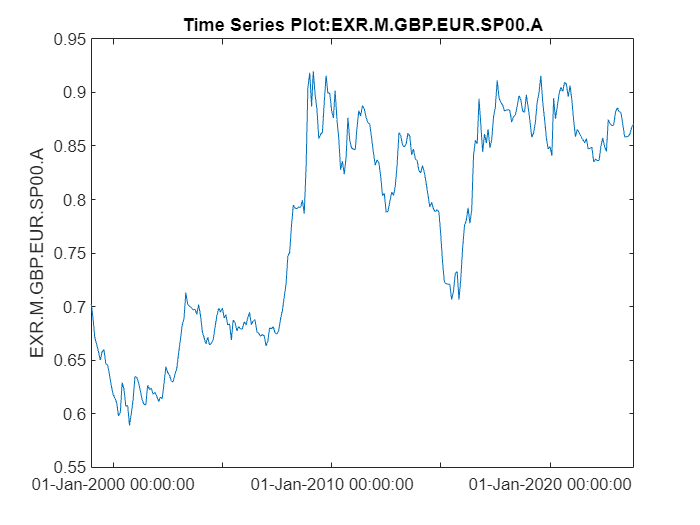

plot(tts{1})


flows = sdmx.getFlows('EUROSTAT')

flows =   Map with properties:

        Count: 7483
      KeyType: char
    ValueType: char


flows.keys

ans = 1×7483 cell array
  Columns 1 through 1310

    {'ESTAT,AACT_ALI0…'}    {'ESTAT,AACT_ALI0…'}    {'ESTAT,AACT_ALI0…'}    {'ESTAT,AACT_EAA0…'}    {'ESTAT,AACT_EAA0…'}    {'ESTAT,AACT_EAA0…'}    {'ESTAT,AACT_EAA0…'}    {'ESTAT,AACT_EAA0…'}    {'ESTAT,AACT_EAA0…'}    {'ESTAT,AACT_EAA0…'}    {'ESTAT,AACT_UV01…'}    {'ESTAT,AACT_UV02…'}    {'ESTAT,AACT_UV03…'}    {'ESTAT,ACF_D_EQ,…'}    {'ESTAT,ACF_D_EQ1…'}    {'ESTAT,ACF_D_LO,…'}    {'ESTAT,ACF_D_LO1…'}    {'ESTAT,ACF_D_OTH…'}    {'ESTAT,ACF_D_REA…'}    {'ESTAT,ACF_P_CH,…'}    {'ESTAT,ACF_P_FA,…'}    {'ESTAT,ACF_P_FI,…'}    {'ESTAT,ACF_P_NE,…'}    {'ESTAT,ACF_P_PU,…'}    {'ESTAT,ACF_P_SO,…'}    {'ESTAT,ACF_S_INF…'}    {'ESTAT,ACF_S_NE,…'}    {'ESTAT,ACF_S_OWN…'}    {'ESTAT,ACF_S_TY,…'}    {'ESTAT,AEI_EF_IR…'}    {'ESTAT,AEI_EF_LS…'}    {'ESTAT,AEI_EF_LU…'}    {'ESTAT,AEI_FM_MS…'}    {'ESTAT,AEI_FM_SA…'}    {'ESTAT,AEI_FM_US…'}    {'ESTAT,AEI_HRI,1.0'}    {'ESTAT,AEI_PESTS…'}    {'ESTAT,AEI_PESTU…'}    {'ESTAT,AEI_PR_GN…'}    {'ESTAT,A

flows.values

ans = 1×7483 cell array
  Columns 1 through 1313

    {'Agricultural la…'}    {'Agricultural la…'}    {'Agricultural la…'}    {'Economic accoun…'}    {'Economic accoun…'}    {'Economic accoun…'}    {'Economic accoun…'}    {'Economic accoun…'}    {'Economic accoun…'}    {'Economic accoun…'}    {'Unit values at …'}    {'Unit values at …'}    {'Unit values: qu…'}    {'Success rate in…'}    {'Reasons for par…'}    {'Success rate in…'}    {'Reasons for par…'}    {'Success rate in…'}    {'Reasons for cho…'}    {'Perception of t…'}    {'Factors, likely…'}    {'Finance types, …'}    {'Enterprises per…'}    {'Potential purpo…'}    {'Envisaged finan…'}    {'Enterprises see…'}    {'Enterprises nee…'}    {'Ownership situa…'}    {'Typical guarant…'}    {'Share of irriga…'}    {'Share of main l…'}    {'Share of main l…'}    {'Manure storage …'}    {'Pesticide sales'}    {'Consumption of …'}    {'Harmonised risk…'}    {'Pesticide sales…'}    {'Pesticide use i…'}    {'Gross nutrient …'}    {'Estimated


sdmx.getDimensions('EUROSTAT', 'prc_hicp_midx')

2023-12-05T14:38:32.944 INFO       [it.bancaditalia.oss.sdmx.client.RestSdmxClient runQuery] Contacting web service with query: https://ec.europa.eu/eurostat/api/dissemination/sdmx/2.1/dataflow/all/prc_hicp_midx/latest


ans = 1×4 cell array
    {'freq'}    {'unit'}    {'coicop'}    {'geo'}



tts = sdmx.getTimeSeries('EUROSTAT', 'prc_hicp_midx/..CP00.EU+DE+FR')

2023-12-05T14:38:33.171 INFO       [it.bancaditalia.oss.sdmx.client.RestSdmxClient runQuery] Contacting web service with query: https://ec.europa.eu/eurostat/api/dissemination/sdmx/2.1/dataflow/all/prc_hicp_midx/latest
2023-12-05T14:38:33.231 INFO       [it.bancaditalia.oss.sdmx.client.RestSdmxClient runQuery] Contacting web service with query: https://ec.europa.eu/eurostat/api/dissemination/sdmx/2.1/dataflow/all/prc_hicp_midx/latest
2023-12-05T14:38:33.279 INFO       [it.bancaditalia.oss.sdmx.client.RestSdmxClient runQuery] Contacting web service with query: https://ec.europa.eu/eurostat/api/dissemination/sdmx/2.1/data/ESTAT%2CPRC_HICP_MIDX%2C1.0/..CP00.EU%2BDE%2BFR


tts = 1×9 cell array
    {1×1 timeseries}    {1×1 timeseries}    {1×1 timeseries}    {1×1 timeseries}    {1×1 timeseries}    {1×1 timeseries}    {1×1 timeseries}    {1×1 timeseries}    {1×1 timeseries}


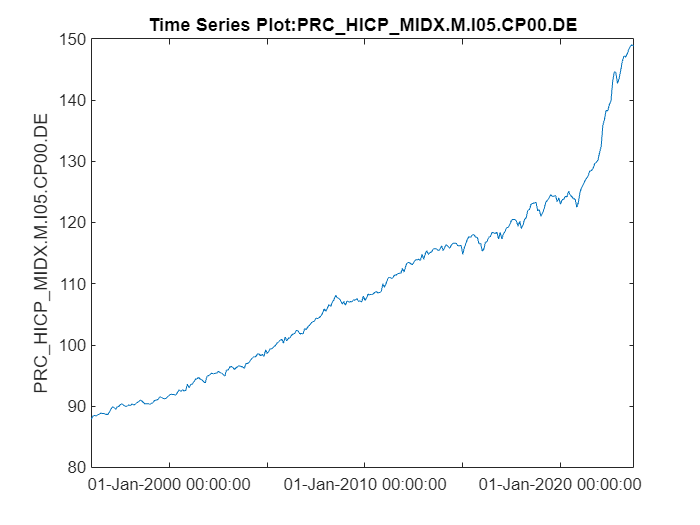

plot(tts{1})


sdmxHelp